Rešujemo Poissonovo enačbo -$\Delta$u = f na pravokotniku (0,1) $\times$ (0, 2) za funkcijo $f(x,y) = -24(x-y)^2$, pri robnih pogojih $g(x,0) = x^4$ in $g(x, 2) = (x-2)^2$ za $0 \leq x \leq 1$ in $g(0, y) = y^4$ in $g(1,y) = (y-1)^4$ za $0 \leq y \leq 2$. Točna rešitev je $f_{tocna}(x,y) = (x-y)^4$.

a = 0;
b = 1;
c = 0;
d = 2;

f = @(x, y) -24*(x - y)^2;
f_tocna = @(x, y) (x - y)^4;

g_north = @(x, y) (x - 2)^4;
g_south = @(x, y) x^4;
g_west = @(x, y) y^4;
g_east = @(x, y) (y - 1)^4;

Preverimo metode za delitev $J = 20$, $K = 40$, $10000$ korakov in natančnost $10^{-8}$. Kasneje smo s pomočjo matrike sistema izračunali optimalno omego, ki je $\omega = 1.7867$.

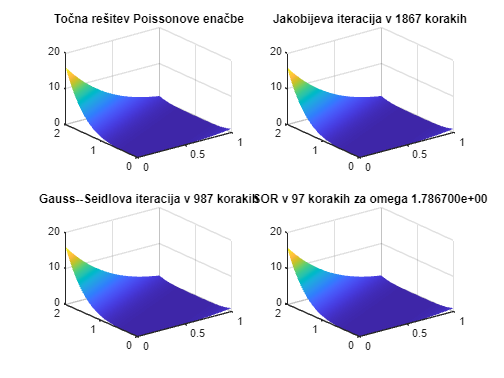

J = 20;
K = 40;

[U, F, tx, ty, delta, X, Y] = pripraviSistem(a, b, c, d, J, K, f, g_north, g_east, g_south, g_west);

tocna = zeros(K + 2, J + 2);
for k = 1:(K+2)
    for j = 1:(J+2)     
       tocna(k,j) = f_tocna(X(k,j),Y(k,j));
    end
end

omega = 1.7867;

[jacobi, koraki_j] = jacobiMetoda(U, F, tx, ty, delta, 10000, 1e-8);
[gaussSeidel, koraki_gs] = gaussSeidelMetoda(U, F, tx, ty, delta, 10000, 1e-8);
[sor, koraki_sor] = sorMetoda(U, F, tx, ty, delta, 10000, 1e-8, omega);

figure;
subplot(2,2,1); surf(X, Y, tocna, 'EdgeColor','none', 'FaceColor','interp'); title('Točna rešitev Poissonove enačbe');
subplot(2,2,2); surf(X, Y, jacobi, 'EdgeColor','none', 'FaceColor','interp'); title(sprintf('Jakobijeva iteracija v %d korakih', koraki_j));
subplot(2,2,3); surf(X, Y, gaussSeidel, 'EdgeColor','none', 'FaceColor','interp'); title(sprintf('Gauss--Seidlova iteracija v %d korakih', koraki_gs));
subplot(2,2,4); surf(X, Y, sor, 'EdgeColor','none', 'FaceColor','interp'); title(sprintf('SOR v %d korakih za omega %d', koraki_sor, omega));

Napake so:

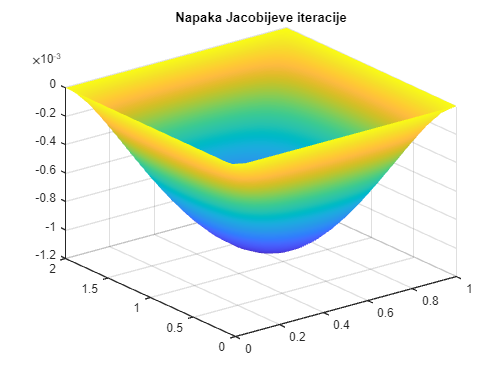

figure; surf(X, Y, tocna - jacobi, 'EdgeColor','none', 'FaceColor','interp'); title('Napaka Jacobijeve iteracije');

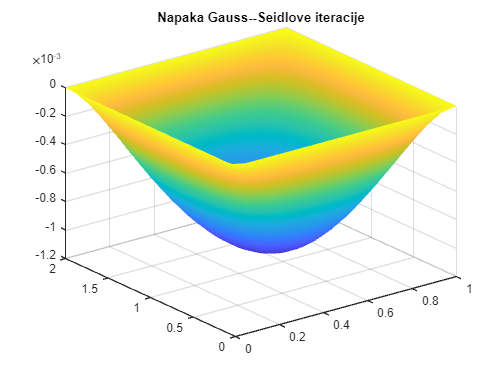

figure; surf(X, Y, tocna - gaussSeidel, 'EdgeColor','none', 'FaceColor','interp'); title('Napaka Gauss--Seidlove iteracije');

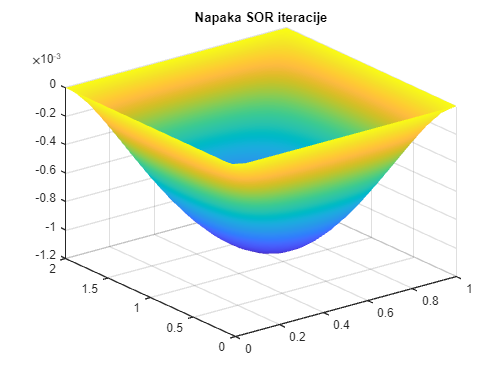

figure; surf(X, Y, tocna - sor, 'EdgeColor','none', 'FaceColor','interp'); title('Napaka SOR iteracije');

Graf prikazuje  število korakov  v odvisnosti od parametra omega pri natančnosti $10^{-8}$. Iz njega lahko ocenimo optimalno $\omega$.

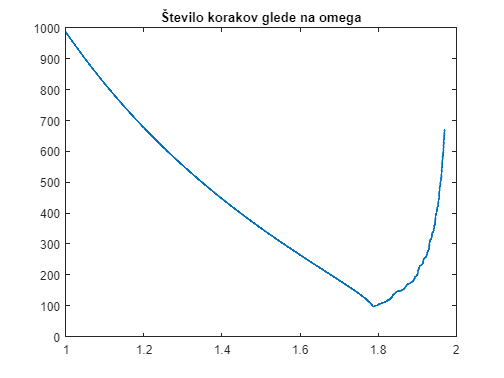

omega_test = 1:0.0001:1.97;

koraki_omega = zeros(1, length(omega_test));

for i = 1:length(omega_test)
    [sor, koraki_sor] = sorMetoda(U, F, tx, ty, delta, 10000, 1e-8, omega_test(i));
    koraki_omega(i) = koraki_sor;
end

figure; plot(omega_test, koraki_omega, 'LineWidth', 1.5); title('Število korakov glede na omega');

Naše ugibanje potrdimo še numerično s pomočjo formule iz predavanj.

A = matrikaSistema(a,b,c,d,J,K);
radij = eigs(eye(size(A,1)) - A, 1, 'largestabs');
omega_opt = 2/(1 + sqrt(1 - radij^2))

omega_opt = 1.7867

Pri različnih izbirah delilnih točk opazujemo potrebno število korakov posamezne metode, da skonvergira do želene natančnosti. 

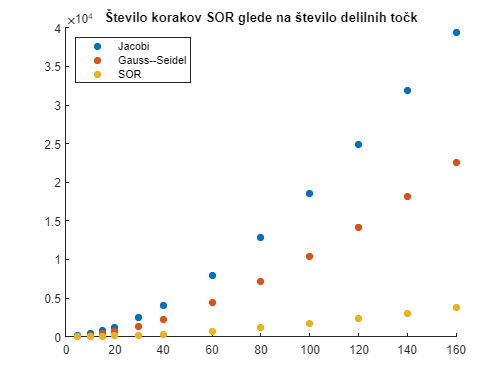

J_test = [5, 10, 15, 20, 30, 40, 60, 80, 100, 120, 140, 160];
K_test = 2 * J_test;

korak_j = zeros(1, length(J_test));
korak_gs = zeros(1, length(J_test));
korak_sor = zeros(1, length(J_test));

for i = 1:length(J_test)
    [U, F, tx, ty, delta, X, Y] = pripraviSistem(a, b, c, d, J_test(i), K_test(i), f, g_north, g_east, g_south, g_west);

    [jacobi, koraki_j] = jacobiMetoda(U, F, tx, ty, delta, 100000, 1e-6);
    [gaussSeidel, koraki_gs] = gaussSeidelMetoda(U, F, tx, ty, delta, 100000, 1e-6);
    [sor, koraki_sor] = sorMetoda(U, F, tx, ty, delta, 100000, 1e-6, omega);

    korak_j(i) = koraki_j;
    korak_gs(i) = koraki_gs;
    korak_sor(i) = koraki_sor;

end

figure;
scatter(J_test, korak_j, 'filled'); hold on;
scatter(J_test, korak_gs, 'filled'); hold on;
scatter(J_test, korak_sor, 'filled'); title('Število korakov SOR glede na število delilnih točk');
legend('Jacobi', 'Gauss--Seidel', 'SOR', 'Location','northwest')

Pri fiksni izbiri delilnih točk si ogledamo čas, ki ga posamezna metoda porabi, da skonvergira.

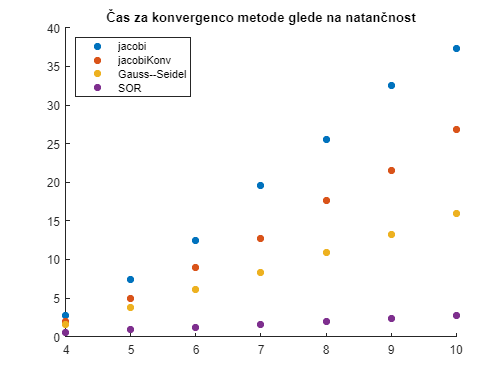

natancnost = 4:1:10;
cas_jacobi = zeros(1, length(natancnost));
cas_jacobiKonv = zeros(1, length(natancnost));
cas_gs = zeros(1, length(natancnost));
cas_sor = zeros(1, length(natancnost));

J = 160;
K = 320;

[U, F, tx, ty, delta, X, Y] = pripraviSistem(a, b, c, d, J, K, f, g_north, g_east, g_south, g_west);

for i = 1:length(natancnost)
    tic
    [jacobi, koraki_j] = jacobiMetoda(U, F, tx, ty, delta, 1000000, 10^-natancnost(i));
    cas_jacobi(i) = toc;
    tic
    [gs, koraki_gs] = gaussSeidelMetoda(U, F, tx, ty, delta, 1000000, 10^-natancnost(i));
    cas_gs(i) = toc;
    tic
    [sor, koraki_sor] = sorMetoda(U, F, tx, ty, delta, 1000000, 10^-natancnost(i), omega);
    cas_sor(i) = toc;
    tic
    [jacobiKonv, koraki_jk] = jacobiKonvolucija(U, F, tx, ty, delta, 1000000, 10^-natancnost(i));
    cas_jacobiKonv(i) = toc;
end

figure;
scatter(natancnost, cas_jacobi, 'filled'); hold on;
scatter(natancnost, cas_jacobiKonv, 'filled'); hold on;
scatter(natancnost, cas_gs, 'filled'); hold on;
scatter(natancnost, cas_sor, 'filled'); title('Čas za konvergenco metode glede na natančnost')
legend('jacobi', 'jacobiKonv', 'Gauss--Seidel', 'SOR', 'Location', 'northwest')